## Boas Práticas

clear all;
close all
clc;

## Leitura do arquivo .wav - audioread


%[Y, FS] = audioread('Audio03.wav')
load('Voz.mat')
% Y é a amplitude, e FS é a frequencia do sinal lido

% TS = tempo entre dois pontos
% TS = 1/FS
% Npontos = quantidade de pontos gravados
% Npontos = length(Y);
% Vfinal é o tempo do audio
% Vfinal = (Npontos-1)*TS
% Vetor tempo usado para plots
% tempo = linspace(0,Vfinal,Npontos)

% figure(1);

% subplot(2,1,1)
% plot(tempo, Y(:,1))
% xlabel("Tempo em segundos")
% ylabel("Amplitude do sinal")
% title("Canal esquerdo")
% subplot(2,1,2)
% plot(tempo, Y(:,2))
% xlabel("Tempo em segundos")
% ylabel("Amplitude od sinal")
% title("Canal Direito")

## Ouvir um arquivo .wav

%sound(Y,FS);

## FFT


FY = fftshift(fft(Vp));

## Visualizar o FFT

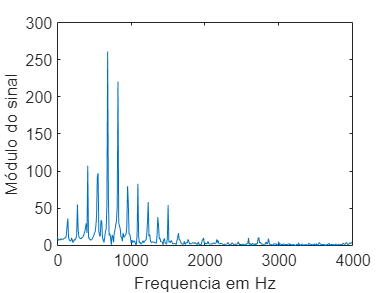

%frequencia = linspace(-FS/2,FS/2,Npontos);

%figure(2)

%subplot(2,1,1)
plot(frequencia,abs(FY(401:end,1)))
xlabel("Frequencia em Hz")
ylabel("Módulo do sinal")

%title("Canal esquerdo")

% subplot(2,1,2)
% plot(frequencia,angle(FY(:,1)))
% xlabel("Frequencia em Hz")
% ylabel("Fase do sinal")
% title("Canal esquerdo")

% subplot(2,1,1)
% xlim([-3000, 3000])
% ylim([24 7400])
%plot(t)
%plot(time)
TS = t(800)/800;
FS = 1/TS

FS = 8000